# AE681A PROJECT

clc, clear

## Defining Material Properties AS4 - 3501-6 epoxy

% Fibre
E1_f = 225;
E2_f = 15;
E3_f = E2_f;
G12_f = 15;
v12_f = 0.2;
v13_f = v12_f;
G23_f = 7;
v21_f = (E2_f*v12_f)/E1_f;
v31_f = (E2_f*v12_f)/E1_f;
v23_f = (E2_f/(2*G23_f)) - 1;

% Matrix
E_m = 4.2;
v_m = 0.34;
G_m = 1.567;
k_m = (E_m*(1 - 2*v_m))/3;

% volume fraction
vf = 0.6;
vm = 1 - vf;
vf_variable = linspace(0, 1, 100);
vm_variable = 1 - vf_variable;

% Compliance, Stiffness Matrix - fibre
S_f = zeros(6);

S_f(1,1) = 1/E1_f;
S_f(2,2) = 1/E2_f;
S_f(3,3) = 1/E3_f;

S_f(1,2) = -v21_f/E2_f;
S_f(1,3) = -v31_f/E3_f;
S_f(2,1) = S_f(1,2);
S_f(3,1) = S_f(1,3);
S_f(3,2) = -v23_f/E3_f;
S_f(2,3) = S_f(3,2);

S_f(4,4) = 1/G23_f;
S_f(5,5) = 1/G12_f;
S_f(6,6) = 1/G12_f;

C_f = S_f^-1;

% Compliance, Stiffness Matrix - Matrix
S_m = zeros(6);

for i = 1:3
    for j = 1:3
        S_m(i,j) = -v_m/E_m;
    end    
    S_m(i,i) = 1/E_m;
    S_m(i+3,i+3) = 1/G_m;
end 

C_m = S_m^-1;

## Strength of material Approach

for i = 1:length(vf_variable)
    E1_Som(i) = (E1_f.*vf_variable(i)) + (E_m.*vm_variable(i));    
    v12_Som(i) = (v12_f.*vf_variable(i)) + (v_m.*vm_variable(i));
    E2_Som(i) = ((vf_variable(i)./E2_f) + (vm_variable(i)./E_m))^-1;
    eeta_f(i) = ((E1_f.*vf_variable(i)) + (((1-(v12_f.*v21_f)).*E_m) + (v_m.*v21_f.*E1_f)).*vm_variable(i))/((E1_f.*vf_variable(i))+(E_m.*vm_variable(i)));
    eeta_m(i) = ((E_m.*vm_variable(i)) + ((((1-(v_m.^2)).*E1_f) - ((1 - (v_m.*v12_f)).*E_m)).*vf_variable(i)))/((E1_f.*vf_variable(i)) + (E_m.*vm_variable(i)));
    E2_ESom(i) = (((eeta_f(i).*vf_variable(i))./E2_f) + ((eeta_m(i).*vm_variable(i))./E_m)).^-1;
    G12_Som(i) = ((vf_variable(i)./G12_f) + (vm_variable(i)./G_m)).^-1;
end 


## Voight approximation

C_voight = zeros(6,6,length(vf_variable));
for i = 1:length(vf_variable)
    C_voight(:,:,i) = (vf_variable(i)*C_f) + (vm_variable(i)*C_m);
end
S_voight = zeros(6,6,length(vf_variable));
for i = 1:length(vf_variable)
    S_voight(:,:,i) = (C_voight(:,:,i))^-1;
end
for i = 1:length(vf_variable)
    E1_voight(i) = 1/S_voight(1,1,i);
    E2_voight(i) = 1/S_voight(2,2,i);
    v12_voight(i) = -S_voight(2,1,i)/S_voight(1,1,i);
    v21_voight(i) = -S_voight(1,2,i)/S_voight(2,2,i);
    v23_voight(i) = -S_voight(3,2,i)/S_voight(2,2,i);
    v32_voight(i) = -S_voight(2,3,i)/S_voight(3,3,i);
    G12_voight(i) = 1/S_voight(5,5,i);
    G23_voight(i) = 1/S_voight(4,4,i);
end 

## Reuss approximation

S_reuss = zeros(6,6,length(vf_variable));
for i = 1:length(vf_variable)
    S_reuss(:,:,i) = (vf_variable(i)*S_f) + (vm_variable(i)*S_m);
end

for i = 1:length(vf_variable)
    E1_reuss(i) = 1/S_reuss(1,1,i);
    E2_reuss(i) = 1/S_reuss(2,2,i);
    v12_reuss(i) = -S_reuss(2,1,i)/S_reuss(1,1,i);
    v21_reuss(i) = -S_reuss(1,2,i)/S_reuss(2,2,i);
    v23_reuss(i) = -S_reuss(3,2,i)/S_reuss(2,2,i);
    v32_reuss(i) = -S_reuss(2,3,i)/S_reuss(3,3,i);
    G12_reuss(i) = 1/S_reuss(5,5,i);
    G23_reuss(i) = 1/S_reuss(4,4,i);
end 


## Concentric Cylinder Assemblage Model

a = ones(1,length(vf_variable));
b = ((a.^2)./vf_variable).^0.5;
P = 1;
a1 = P*((a.^2).*(C_m(1,1) - C_m(1,2))*(C_f(1,2) - C_m(1,2)) + (b.^2).*(C_m(1,2)*(C_f(1,2) - C_m(1,2)) + C_m(1,1)*(C_f(1,2) + C_m(1,2))));
a2 = P*((a.^2).*(C_m(1,1) - C_m(1,2))*(C_f(1,2) - C_m(1,2)) + (b.^2).*C_m(1,2)*(C_m(1,1) - C_m(1,2) + C_f(2,2) + C_f(2,3)));
a4 = P*((a.^2).*(C_m(1,1) - C_m(1,2))*(C_m(1,1) + C_m(1,2) - C_f(2,2) - C_f(2,3)) - (b.^2).*(C_m(1,1) + C_m(1,2))*(C_m(1,1) - C_m(1,2) + C_f(2,2) + C_f(2,3)));

b1 = (-b.^4).*((C_m(1,1)^2) + C_m(1,1)*C_m(1,2) - (2*(C_m(1,2)^2)))*(C_m(1,1) - C_m(1,2) + C_f(2,2) + C_f(2,3));
b2 = (a).*(C_m(1,1) - C_m(1,2))*(-(C_m(1,1)^2) + 2*((C_f(1,2) - C_m(1,2))^2) + C_f(1,1)*(C_m(1,1) + C_m(1,2) - C_f(2,2) - C_f(2,3)) + C_m(1,1)*(-C_m(1,2) + C_f(2,2) + C_f(2,3)));
b3 = (-b.^2).*(C_f(1,1)*(C_m(1,1) + C_m(1,2))*(C_m(1,1) - C_m(1,2) + C_f(2,2) + C_f(2,3)) - 2*((C_m(1,1)^3) + C_m(1,2)*((C_f(1,2)^2) - 2*C_f(1,2)*C_m(1,2) + C_m(1,2)*(2*C_m(1,2) - C_f(2,2) - C_f(2,3)) + C_m(1,1)*((C_f(1,2)^2) + 2*C_f(1,2)*C_m(1,2) + C_m(1,2)*(-3*C_m(1,2) + C_f(2,2) + C_f(2,3))))));

d = pi.*(b1 + b2 + b3);
exx = a4./d;
E1_CCA = P./(pi.*(b.^2).*exx);
k23_CCA = (-vf_variable.*(C_m(1,1) - C_m(1,2))*(C_m(1,1) + C_m(1,2) - C_f(2,2) - C_f(2,3)) + (C_m(1,1) + C_m(1,2))*(C_m(1,1) - C_m(1,2) + C_f(2,2) + C_f(2,3)))./(2*(vf_variable.*(C_m(1,1) + C_m(1,2) - C_f(2,2) - C_f(2,3)) + (C_m(1,1) - C_m(1,2) + C_f(2,2) + C_f(2,3))));
G12_CCA = (G_m*(G12_f.*(1 + vf_variable) + G_m*(1 - vf_variable)))./(G12_f*(1 - vf_variable) + G_m*(1 + vf_variable));
G23_CCA = G_m*(1 + (vf_variable))./((G_m)/(G23_f - G_m) + ((k_m + (7/3)*G_m)/(2*k_m + (8/3)*G_m)));
v12_CCA = (2*vf_variable*C_m(1,1)*C_f(1,2) + (1 - vf_variable)*C_m(1,2)*(C_m(1,1) - C_m(1,2) + C_f(2,2) + C_f(2,3)))/((-vf_variable)*(C_m(1,1) - C_m(1,2))*(C_m(1,1) + C_m(1,2) - C_f(2,2) - C_f(2,3)) + (C_m(1,1) + C_m(1,2))*(C_m(1,1) - C_m(1,2) + C_f(2,2) + C_f(2,3)));
E2_CCA = (4*G23_CCA.*k23_CCA)./(k23_CCA + G23_CCA + (4*(v12_CCA.^2).*G23_CCA.*k23_CCA));
v23_CCA = (k23_CCA - G23_CCA - (4*(v12_CCA.^2).*G23_CCA.*k23_CCA)./E1_CCA)./(k23_CCA + G23_CCA + (4*(v12_CCA.^2).*G23_CCA.*k23_CCA)./E1_CCA);
v21_CCA = (4.*v12_CCA.*G23_CCA.*k23_CCA)./(E1_CCA.*(k23_CCA + G23_CCA) + 4*(v12_CCA.^2).*G23_CCA.*k23_CCA);


## Mori Tanaka Method

% Defining Hills Moduli
n_m = C_m(1,1);
k_m = (C_m(2,2) + C_m(2,3))/2;
m_m = (C_m(2,2) - C_m(2,3))/2;
l_m = C_m(1,2);
p_m = C_m(5,5);

n_f = C_f(1,1);
k_f = (C_f(2,2) + C_f(2,3))/2;
m_f = (C_f(2,2) - C_f(2,3))/2;
l_f = C_f(1,2);
p_f = C_f(5,5);

k = (vf_variable*k_f*(k_m + m_m) + vm_variable*k_m*(k_f + m_m))./(vf_variable*(k_m + m_m) + vm_variable*(k_f + m_m));
l = (vf_variable*l_f*(k_m + m_m) + vm_variable*l_m*(k_f + m_m))./(vf_variable*(k_m + m_m) + vm_variable*(k_f + m_m));
n = vm_variable*n_m + vf_variable*n_f + (1 - vf_variable*l_f - vm_variable*l_m)*((l_f - l_m)/(k_f - m_m));
m = (m_f*m_m*(k_m + 2*m_m) + k_m*m_m*(vf_variable*m_f + vm_variable*m_m))./(k_m*m_m + (k_m + 2*m_m)*(vf_variable*m_m + vm_variable*m_f));
p = (2*vf_variable*p_m*p_f + vm_variable*(p_m*p_f + p_m^2))./(2*vf_variable*p_m + vm_variable*(p_f + p_m));

C_MTM = zeros(6,6,length(vf_variable));
for i = 1:length(vf_variable)

    C_MTM(1,1,i) = n(i);
    C_MTM(2,2,i) = k(i) + m(i);
    C_MTM(3,3,i) = k(i) + m(i);
    C_MTM(4,4,i) = m(i);
    C_MTM(5,5,i) = p(i);
    C_MTM(6,6,i) = p(i);
    C_MTM(1,2,i) = l(i);
    C_MTM(2,1,i) = l(i);
    C_MTM(1,3,i) = l(i);
    C_MTM(3,1,i) = l(i);
    C_MTM(2,3,i) = k(i) - m(i);
    C_MTM(3,2,i) = k(i) - m(i);
end

S_MTM = zeros(6,6,length(vf_variable));
for i = 1:length(vf_variable)
    S_MTM(:,:,i) = (C_MTM(:,:,i))^-1;
end
for i = 1:length(vf_variable)
    E1_MTM(i) = 1/S_MTM(1,1,i);
    E2_MTM(i) = 1/S_MTM(2,2,i);
    v12_MTM(i) = -S_MTM(2,1,i)/S_MTM(1,1,i);
    v21_MTM(i) = -S_MTM(1,2,i)/S_MTM(2,2,i);
    v23_MTM(i) = -S_MTM(3,2,i)/S_MTM(2,2,i);
    v32_MTM(i) = -S_MTM(2,3,i)/S_MTM(3,3,i);
    G12_MTM(i) = 1/S_MTM(5,5,i);
    G23_MTM(i) = 1/S_MTM(4,4,i);
end 


## Hashin Strikman

E1_HSminus = E_m.*vm_variable + E1_f.*vf_variable + (4.*((v12_f - v_m)^2).*vf_variable.*vm_variable)./((vm_variable/k_f) + (vf_variable/k_m) + (1/G_m));
E1_HSplus = E_m.*vm_variable + E1_f.*vf_variable + (4.*((v12_f - v_m)^2).*vf_variable.*vm_variable)./((vm_variable/k_f) + (vf_variable/k_m) + (1/G23_f));
v12_HSminus = v_m*vm_variable + v12_f*vf_variable + (4*(v_m - v12_f)*(1/(k_f - k_m))*vf_variable.*vm_variable)./((vm_variable/k_f) + (vf_variable/k_m) + (1/G23_f));
v12_HSplus = v_m*vm_variable + v12_f*vf_variable + (4*(v12_f - v_m)*(1/(k_m - k_f))*vf_variable.*vm_variable)./((vm_variable/k_f) + (vf_variable/k_m) + (1/G_m));
G12_HSminus = G_m*(((G_m*vm_variable) + G12_f*(1 + vf_variable)))./(G12_f*vm_variable + G_m*(1 + vf_variable));
G12_HSplus = G12_f*(((G12_f*vf_variable) + G_m*(1 + vm_variable)))./(G_m*vf_variable + G12_f*(1 + vm_variable));


## Hills Method    

Element_Vol = readmatrix("S11_Evol.csv");
Element_Vol_fibre = Element_Vol(2:7101,12);
fibre_volume = sum(Element_Vol_fibre)

fibre_volume = 598.7637

Element_Vol_matrix = Element_Vol(7102:end,12);
matrix_volume = sum(Element_Vol_matrix)

matrix_volume = 401.1656


stress11 = readmatrix("S11_Stress.csv");
stress11_fibre = stress11(2:7101,13:18);
stress11_matrix = stress11(7101:end,13:18);

stress22 = readmatrix("S22_Stress.csv");
stress22_fibre = stress22(2:7101,13:18);
stress22_matrix = stress22(7102:end,13:18);

stress33 = readmatrix("S33_Stress.csv");
stress33_fibre = stress33(2:7101,13:18);
stress33_matrix = stress33(7102:end,13:18);

stress12 = readmatrix("S12_Stress.csv");
stress12_fibre = stress12(2:7101,13:18);
stress12_matrix = stress12(7102:end,13:18);

stress13 = readmatrix("S13_Stress.csv");
stress13_fibre = stress13(2:7101,13:18);
stress13_matrix = stress13(7102:end,13:18);

stress23 = readmatrix("S23_Stress.csv");
stress23_fibre = stress23(2:7101,13:18);
stress23_matrix = stress23(7102:end,13:18);
 
vol_stress_fibre = zeros(6,6);
for i = 1:7100
    for j = 1:6
        vol_stress_fibre(j,1) = vol_stress_fibre(j,1) +  stress11_fibre(i,j)*Element_Vol_fibre(i);
        vol_stress_fibre(j,2) = vol_stress_fibre(j,2) +  stress22_fibre(i,j)*Element_Vol_fibre(i);
        vol_stress_fibre(j,3) = vol_stress_fibre(j,3) +  stress33_fibre(i,j)*Element_Vol_fibre(i);
        vol_stress_fibre(j,4) = vol_stress_fibre(j,4) +  stress12_fibre(i,j)*Element_Vol_fibre(i);
        vol_stress_fibre(j,5) = vol_stress_fibre(j,5) +  stress13_fibre(i,j)*Element_Vol_fibre(i);
        vol_stress_fibre(j,6) = vol_stress_fibre(j,6) +  stress23_fibre(i,j)*Element_Vol_fibre(i);
    end
end

vol_stress_matrix = zeros(6,6);
for i = 1:3919
    for j = 1:6
        vol_stress_matrix(j,1) = vol_stress_matrix(j,1) +  stress11_matrix(i,j)*Element_Vol_matrix(i);
        vol_stress_matrix(j,2) = vol_stress_matrix(j,2) +  stress22_matrix(i,j)*Element_Vol_matrix(i);
        vol_stress_matrix(j,3) = vol_stress_matrix(j,3) +  stress33_matrix(i,j)*Element_Vol_matrix(i);
        vol_stress_matrix(j,4) = vol_stress_matrix(j,4) +  stress12_matrix(i,j)*Element_Vol_matrix(i);
        vol_stress_matrix(j,5) = vol_stress_matrix(j,5) +  stress13_matrix(i,j)*Element_Vol_matrix(i);
        vol_stress_matrix(j,6) = vol_stress_matrix(j,6) +  stress23_matrix(i,j)*Element_Vol_matrix(i);
    end
end

stress_conc_fibre = (vol_stress_fibre./fibre_volume).*10^-6;
stress_conc_matrix = (vol_stress_matrix./matrix_volume).*10^-6;

A = 0.6*stress_conc_fibre + 0.4*stress_conc_matrix

A =     0.9982   -0.0003   -0.0003    0.0000    0.0000   -0.0000
   -0.0000    0.9999   -0.0001   -0.0000   -0.0000   -0.0000
   -0.0009   -0.0001    0.9999    0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0000    1.0002   -0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    1.0003    0.0000
   -0.0001    0.0000    0.0000    0.0000    0.0000    1.0000



S_hills = vf*stress_conc_fibre*S_f + vm*stress_conc_matrix*S_m;

E1_Hills = 1/S_hills(1,1)

E1_Hills = 21.9722

E2_Hills = 1/S_hills(2,2)

E2_Hills = 7.3828

v12_Hills = -S_hills(2,1)/S_hills(1,1)

v12_Hills = 0.7225

v21_Hills = -S_hills(1,2)/S_hills(2,2)

v21_Hills = 0.0897

v23_Hills = -S_hills(3,2)/S_hills(2,2)

v23_Hills = 0.2500

v32_Hills = -S_hills(2,3)/S_hills(3,3)

v32_Hills = 0.2505

G12_hills = 1/S_hills(5,5)

G12_hills = 3.7765

G23_hills = 1/S_hills(4,4)

G23_hills = 3.1782

## Plots

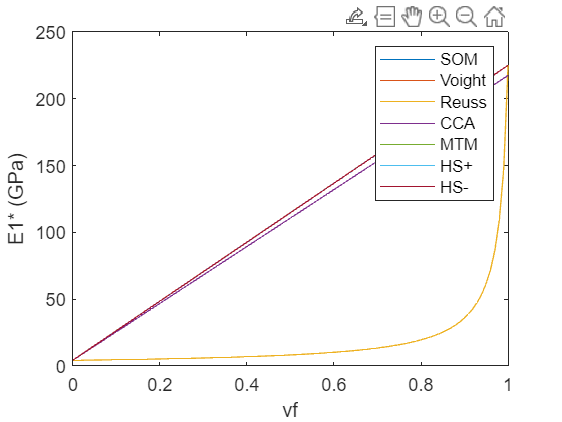

% E1 plot
plot(vf_variable, E1_Som)
hold on
plot(vf_variable, E1_voight)
hold on
plot(vf_variable, E1_reuss)
hold on
plot(vf_variable, E1_CCA)
hold on
plot(vf_variable, E1_MTM)
hold on
plot(vf_variable, E1_HSplus)
hold on
plot(vf_variable, E1_HSminus)
hold off
xlabel("vf")
ylabel("E1* (GPa)")
legend("SOM", "Voight", "Reuss", "CCA", "MTM", "HS+", "HS-")

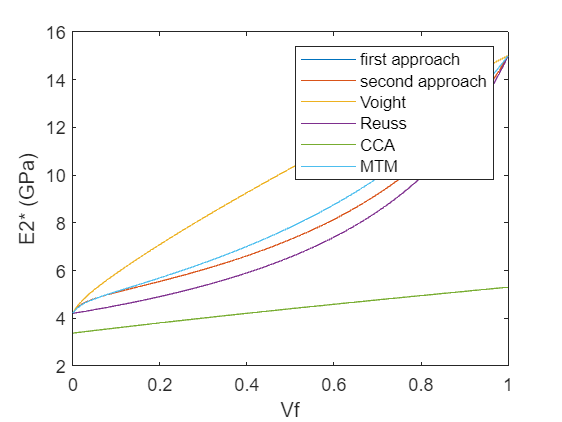


% E2 plot
plot(vf_variable, E2_Som)
hold on
plot(vf_variable, E2_ESom)
hold on
plot(vf_variable, E2_voight)
hold on
plot(vf_variable, E2_reuss)
hold on
plot(vf_variable, E2_CCA)
hold on
plot(vf_variable, E2_MTM)
ylabel("E2* (GPa)")
xlabel("Vf")
legend("first approach", "second approach","Voight", "Reuss","CCA","MTM")
hold off

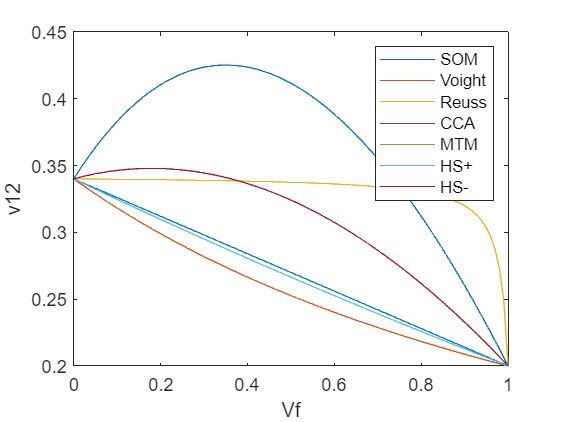


% v12 plot
plot(vf_variable, v12_Som)
hold on
plot(vf_variable, v12_voight)
hold on
plot(vf_variable, v12_reuss)
hold on 
plot(vf_variable, v12_CCA)
hold on
plot(vf_variable, v12_MTM)
hold on
plot(vf_variable, v12_HSplus)
hold on
plot(vf_variable, v12_HSminus)
xlabel("Vf")
ylabel("v12")
legend("SOM", "Voight", "Reuss", "CCA", "MTM", "HS+", "HS-")
hold off

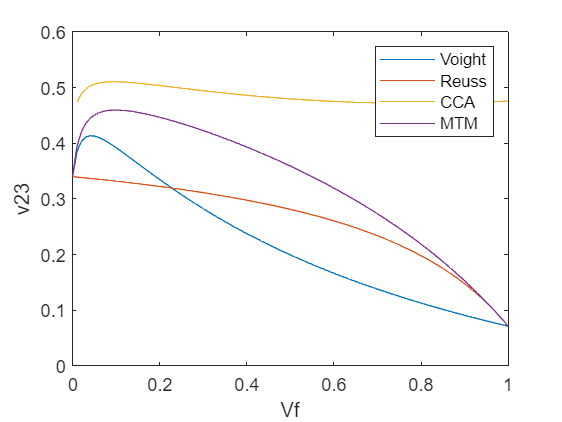


% v23 plot
plot(vf_variable, v23_voight)
hold on
plot(vf_variable, v23_reuss)
hold on
plot(vf_variable, v23_CCA)
hold on
plot(vf_variable, v23_MTM)
xlabel("Vf")
ylabel("v23")
legend("Voight", "Reuss", "CCA", "MTM")
hold off

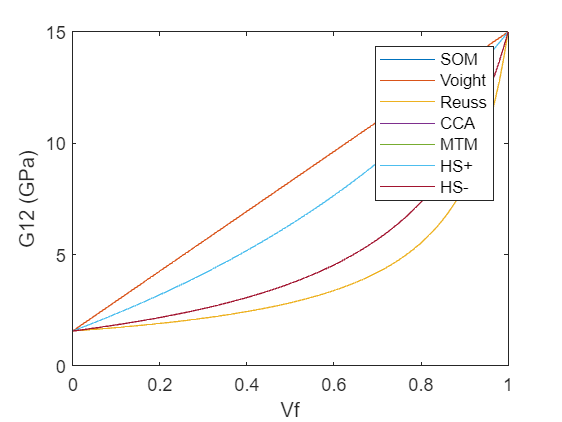


% G12 plot
plot(vf_variable, G12_Som)
hold on
plot(vf_variable, G12_voight)
hold on
plot(vf_variable, G12_reuss)
hold on
plot(vf_variable, G12_CCA)
hold on
plot(vf_variable, G12_MTM)
hold on
plot(vf_variable, G12_HSplus)
hold on 
plot(vf_variable, G12_HSminus)
xlabel("Vf")
ylabel("G12 (GPa)")
legend("SOM", "Voight", "Reuss","CCA", "MTM", "HS+", "HS-")
hold off

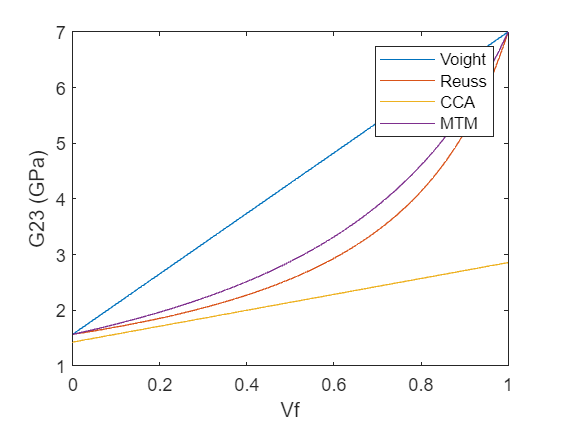


% G23 plot
plot(vf_variable, G23_voight)
hold on
plot(vf_variable, G23_reuss)
hold on
plot(vf_variable, G23_CCA)
hold on
plot(vf_variable, G23_MTM)
xlabel("Vf")
ylabel("G23 (GPa)")
legend("Voight", "Reuss", "CCA", "MTM")
hold off